# Thermodynamics of N-Schlogl

%specify roots
roots = [ 1 2 4 7 8  10 13]

roots =      1     2     4     7     8    10    13


%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end

poly_func = matlabFunction(poly)

poly_func = function_handle with value:
    @(x)-(x-1.0).*(x-2.0).*(x-4.0).*(x-7.0).*(x-8.0).*(x-1.0e+1).*(x-1.3e+1)


%Get rate cosntants 
C = coeffs(poly)

$$C = \left(\begin{array}{cccccccc} 58240 & -127824 & 100540 & -37684 & 7495 & -811 & 45 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccccccc} 58240 & 127824 & 100540 & 37684 & 7495 & 811 & 45 & 1 \end{array}\right)$$

%get forward and backward rates
rplus = 0;
rmin = 0;

for i = 1:size(k_const,2)
    if mod(i,2) == 0
        rmin = rmin + k_const(i)*x^(i-1);
    else 
        rplus = rplus + k_const(i)*x^(i-1);
    end
end
rpoly = rplus - rmin;

%verify rate from roots and rate cosntants is the same
simplify(rpoly-poly)

$$ans = 0$$

%rate across each reaction
r_rxn = [];
%potential change across each reaction
G_rxn = [];

for i = 1:size(k_const,2)/2
     r_rate = k_const(2*i - 1)*x^(2*i-2) -  k_const(2*i)*x^(2*i-1);
    r_rxn = [r_rxn; r_rate];
    G_rxn = [G_rxn; log(rmin/rplus)*r_rate];
end
r_rxn

$$r\_rxn = \left(\begin{array}{c} 58240-127824\,x\\ 100540\,x^{2}-37684\,x^{3}\\ 7495\,x^{4}-811\,x^{5}\\ 45\,x^{6}-x^{7} \end{array}\right)$$

G_rxn

$$G\_rxn = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\,\left(127824\,x-58240\right)\\ \sigma_{1}\,\left(100540\,x^{2}-37684\,x^{3}\right)\\ \sigma_{1}\,\left(7495\,x^{4}-811\,x^{5}\right)\\ \sigma_{1}\,\left(45\,x^{6}-x^{7}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{x^{7}+811\,x^{5}+37684\,x^{3}+127824\,x}{45\,x^{6}+7495\,x^{4}+100540\,x^{2}+58240}\right) \end{array}$$

r_rxn_func = matlabFunction(r_rxn)

r_rxn_func = function_handle with value:
    @(x)[x.*-1.27824e+5+5.824e+4;x.^2.*1.0054e+5-x.^3.*3.7684e+4;x.^4.*7.495e+3-x.^5.*8.11e+2;x.^6.*4.5e+1-x.^7]


G_rxn_func = matlabFunction(G_rxn)

G_rxn_func = function_handle with value:
    @(x)[-log((x.*1.27824e+5+x.^3.*3.7684e+4+x.^5.*8.11e+2+x.^7)./(x.^2.*1.0054e+5+x.^4.*7.495e+3+x.^6.*4.5e+1+5.824e+4)).*(x.*1.27824e+5-5.824e+4);log((x.*1.27824e+5+x.^3.*3.7684e+4+x.^5.*8.11e+2+x.^7)./(x.^2.*1.0054e+5+x.^4.*7.495e+3+x.^6.*4.5e+1+5.824e+4)).*(x.^2.*1.0054e+5-x.^3.*3.7684e+4);log((x.*1.27824e+5+x.^3.*3.7684e+4+x.^5.*8.11e+2+x.^7)./(x.^2.*1.0054e+5+x.^4.*7.495e+3+x.^6.*4.5e+1+5.824e+4)).*(x.^4.*7.495e+3-x.^5.*8.11e+2);log((x.*1.27824e+5+x.^3.*3.7684e+4+x.^5.*8.11e+2+x.^7)./(x.^2.*1.0054e+5+x.^4.*7.495e+3+x.^6.*4.5e+1+5.824e+4)).*(x.^6.*4.5e+1-x.^7)]


%total dissipation
diss = log(rmin/rplus)*poly;
diss_func = matlabFunction(diss);

%plots
x_arr = max(0,min(roots)):abs(min(roots))/10: max(abs(roots));

%rate plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,r_rxn_func(x_arr))
end
plot(x_arr,poly_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×5 string array
    "1"    "2"    "3"    "4"    "total"


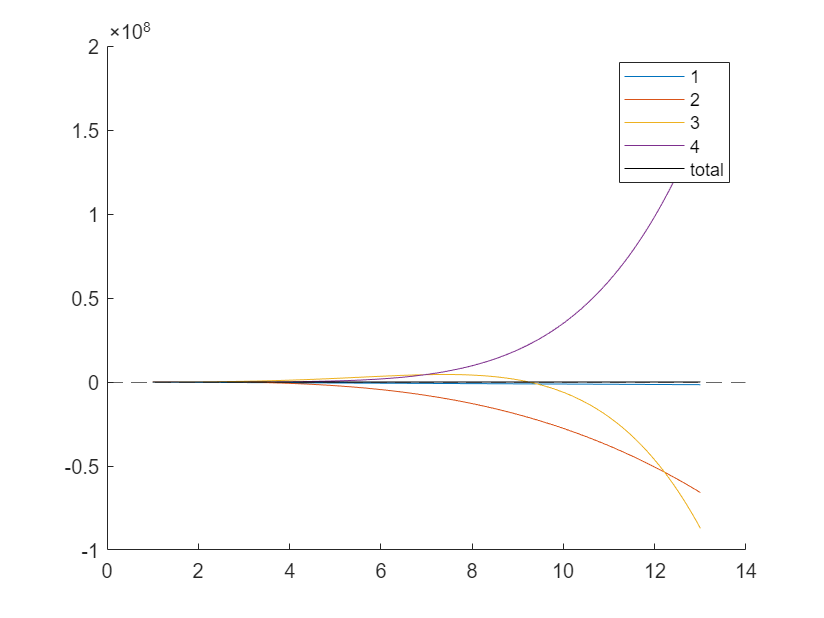

legend(string(label_lst))

%dissipation plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,G_rxn_func(x_arr))
end
plot(x_arr,diss_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×5 string array
    "1"    "2"    "3"    "4"    "total"


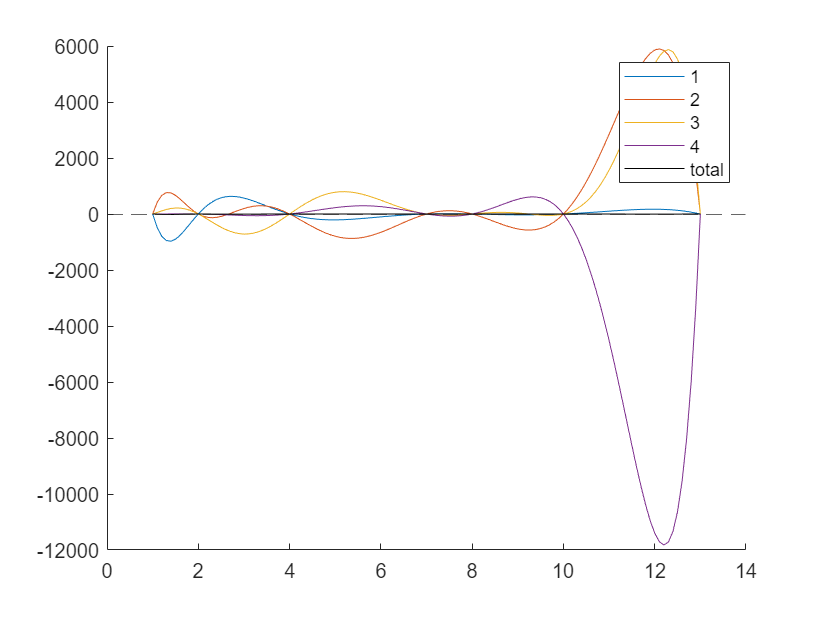

legend(string(label_lst))

label_lst = 1:size(r_rxn,1)

label_lst =      1     2     3     4
